# Time-frequency analysis of power

## **Background**

Time-frequency representations of power are used to quantify brain  responses in the frequency domain. These reposes are often interpreted  to reflect task-related modulations of brain oscillations. In this  section we will show how these response can be estimated by an FFT  approach using a sliding time-window.  

## **Requirements**

The FIFF-file with the raw data: 

*training1.fif  training2.fif *

Sensors and trials left from [Artifact rejection](https://www.chbh.bham.ac.uk/wiki/index.php/Artifact_rejection): 

*chan_keep.mat**trl_keep.mat**chan_keep2.mat**trl_keep2.mat*

The ICA projection from [Artifact suppression by ICA](https://www.chbh.bham.ac.uk/wiki/index.php/Artifact_suppression_by_ICA): 

*planar_comp.mat*

The trial function:  

*ft_trialfun_general.m*

## **Preparing the data**

dataset{1,1} = 'training1.fif';
dataset{1,2} = 'training2.fif';

Before initiating the TFR analysis read in the trials. Read in the trials: 

for i=1:2
   cfg = [];
   cfg.dataset = char(dataset{1,i});  
   cfg.trialfun = 'ft_trialfun_general';  
   cfg.trialdef.eventtype  = 'STI101';  
   cfg.trialdef.eventvalue = [21 22];  
   cfg.trialdef.prestim = 2.5;  
   cfg.trialdef.poststim = 2;  
   cfg  = ft_definetrial(cfg);    
   cfg.channel = {'MEGGRAD'};  
   cfg.demean = 'yes';    
   data(i,1)  = ft_preprocessing(cfg); 
end

cfg=[];
cfg.keepsampleinfo='no';
data_planar=ft_appenddata(cfg,data(1,1),data(2,1));


load trl_keep
load chan_keep
cfg=[];
cfg.trials=trl_keep;
cfg.channel=chan_keep;
planar_rjv1=ft_selectdata(cfg,data_planar);


Apply the ICA projection 

load planar_comp
cfg = [];  
cfg.component = [8 11]; 
planar_ica = ft_rejectcomponent(cfg, planar_comp, planar_rjv1);


Select 'attend left' trials and 'attend right' trials for the two conditions. 

idx=(find(planar_ica.trialinfo==21))';
cfg=[];
cfg.trials=idx;
data_left=ft_selectdata(cfg,planar_ica);
clear idx

idx=(find(planar_ica.trialinfo==22))';
cfg=[];
cfg.trials=idx;
data_right=ft_selectdata(cfg,planar_ica);

## **Perform the time-frequency analysis of power; lower frequencies**

The goal is to calculate the time-frequency of power per trials. The  power will subsequently be averaged over trials. To calculate the power a Fourier transform is applied to a sliding time-window approach. The  length of the time-window (cfg.t_fimwin) is ΔT = 0.5 s. It will be moved in time steps of 0.05 s starting at -1.5 and ending at 1 (cfg.toi).  Prior to calculating the Fourier transform the time window is multiplied by a Hanning taper (also length ΔT). The analysis will be performed  from 1 to 30 Hz in steps of Δf = 2 Hz (cfg.foi). Not that the frequency  steps are dictated by the length of the sliding time-window:  Δf = 1/ΔT. The spectra smoothing is about ΔFs = 1.5 / ΔT = ±3 Hz (the factor 1.5 stems for the Hanning taper).  

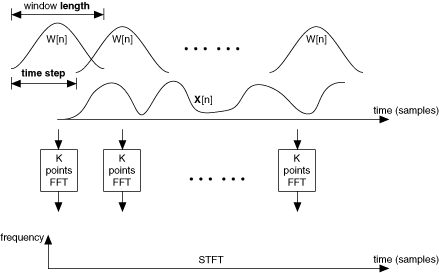

Calculate the time-frequency power for both conditions:  

cfg = [];
cfg.output = 'pow';
cfg.channel = 'MEGGRAD';
cfg.taper = 'hanning';
cfg.method = 'mtmconvol';
cfg.foi          = 2:2:30;
numfoi = length(cfg.foi);
cfg.t_ftimwin    =  ones(length(cfg.foi),1).* 0.5;
cfg.toi          = [-1.8 : 0.05: 1];
cfg.keeptrials = 'no'; 
tfr_low_left = ft_freqanalysis(cfg, data_left);
tfr_low_right = ft_freqanalysis(cfg, data_right);

The TFRs of power for the 203 planar gradiometers (remember we removed 1 sensor previously) have now been produced. Recall that the Elekta/MEGIN system has 306 sensor locations. Each location has two orthogonal  planar gradiometers. The next step is to combine the power of two  gradiometers by a summing those:  

cfg = [];
cfg.method = 'sum';
tfr_low_left_c = ft_combineplanar(cfg,tfr_low_left);
tfr_low_right_c = ft_combineplanar(cfg,tfr_low_right);

This results in 102 TFRs of each of the conditions. 

## **Plotting the TFR of the low frequency results**

In the following analysis we will focus on the time following the  target onset and 'attend left' trials only. Lets first consider the TFR  plot of a single location (MEG2112+MEG2113): 

cfg = [];
cfg.baseline     = 'no'; 
cfg.xlim         = [-0.5 1];
cfg.zlim         = [0 0.7e-23] ;	        
cfg.showlabels   = 'no';	
cfg.channel = 'MEG2112+2113';
ft_singleplotTFR(cfg, tfr_low_left_c);

The power spans from 0 to 0.7e-23. The units are in (T/m)2/Hz. To convert to (fT/m)2/Hz multiply by 1026, i.e. the range is in 0 to 1500 (ft/m)2. In  the plot note the ongoing alpha activity at ~10 Hz. In response to  the cue and stimulus onset there is ~4 to 6 Hz response most likely  reflecting the spectral content of the event-related field.  

To observe the change in power we apply relative baseline (-0.5 to -0.3 s; i.e. just prior to the target onset) (powerpost/powerpre). Note ~100% decrease of power in the alpha band after the grating onset  (time 0s) until the end of the analysed window. In addition note the  short-lived over 100% response in the theta band at the grating onset.  This respons in the theta band likely reflecting the spectral  representation of the event-related field rather than induced  oscillations.  

cfg = [];
cfg.baseline     = [-0.5 -0.3]; 
cfg.baselinetype = 'relative';
cfg.xlim         = [-0.5 1];
cfg.zlim         = [0.4 2] ;	        
cfg.showlabels   = 'no';	
cfg.channel = 'MEG2112+2113';
ft_singleplotTFR(cfg, tfr_low_left_c);

To plot all sensors: 

cfg = [];
cfg.baseline     = [-0.5 -0.3]; 
cfg.baselinetype = 'relative';
cfg.xlim=[-0.5 1];
cfg.zlim         = [0.4 2] ;	        
cfg.layout = 'neuromag306cmb.lay';
ft_multiplotTFR(cfg, tfr_low_left_c);

### **Exercise 1**

Plot the results using an absolute baseline. Why is a relative baseline typically used in group studies?  

### **Exercise 2**

Change the time-window to 0.25 s and plot the results. What is the  main effect in terms of time and frequency smoothing? Also show the  updated cfg. 

### **Exercise 3**

Change the time-window to 1.00 s and plot the results. What is the  main effect  in terms of time and frequency smoothing? Also show the  updated cfg.  

The topographical representation can be plotted as follows:  

cfg = [];
cfg.baseline     = [-0.5 -0.3]; 
cfg.baselinetype = 'relative';
cfg.xlim=[0.35 1];
cfg.ylim = [10 10];
cfg.zlim         = [0.5 1.5] ;	        
cfg.showlabels   = 'no';	
cfg.layout = 'neuromag306cmb.lay';
figure 
ft_topoplotTFR(cfg, tfr_low_left_c);

### **Exercise 4**

Repeat the analysis with the 'attend right' trials. Are there any differences from the results of the 'attend left' trials? 

Finally let's plot the difference between the 'attend left' and 'attend  right' trials. To do so we calculate the difference between the two  conditions divided by their sum. 

tfr_low_diff=tfr_low_left_c;
tfr_low_diff.powspctrm=(tfr_low_left_c.powspctrm-tfr_low_right_c.powspctrm)./(tfr_low_left_c.powspctrm+tfr_low_right_c.powspctrm);

Then plot the resulting power estimates: 

cfg = [];
cfg.xlim=[-1 1];
cfg.zlim         = [-0.3 0.3] ;	        
cfg.showlabels   = 'no';	
cfg.layout       = 'neuromag306cmb.lay';
ft_multiplotTFR(cfg, tfr_low_diff);

Then plot the topography of the alpha repsonse at 10Hz and focus on the  timewindow between the cue onset (-1.2 sec) and grating onset (0 sec).  Lateralized attention shift has repeatedly been reported in the  literature indexed by alpha power lateralization well after the cue just prior to the target onset.   

cfg = [];
cfg.xlim = [-0.5 0];
cfg.ylim = [10 10];
cfg.zlim         = [-0.2 0.2] ;	        
cfg.showlabels   = 'no';	
cfg.layout       = 'neuromag306cmb.lay';
ft_topoplotTFR(cfg, tfr_low_diff);

The resulting plot indicate strong lateralization of the alpha  response over a number of posterior channels when comparing the 'attend  left' and 'attend right' trials. 

To study the topography as a function of time write:  

cfg = [];
cfg.xlim = [-0.6:0.2:0.6];
cfg.ylim = [10 10];
cfg.zlim         = [-0.2 0.2] ;	        
cfg.showlabels   = 'no';	
cfg.layout       = 'neuromag306cmb.lay';
ft_topoplotTFR(cfg, tfr_low_diff);

## **Perform the time-frequency analysis of power; higher frequencies**

For higher frequencies, a multitaper approach is typically applied.  The multitapers serve to smooth the time-frequency representations in  the frequency domain. The smoothing will increase with number of tapers. Since oscillatory gamma activity (~60-90 Hz) often is quite broadband  more spectral smoothing is required compared to lower frequencies.  Several orthogonal tapers might be used for each time window prior to  the calculation of the Fourier transform.  The length of the time-window (cfg.t_fimwin) is ΔT = 0.25 s. It will be moved in steps of 0.05 s  starting at -1.5 and ending at 1.5 (cfg.toi). The analysis will be  performed from 30 to 100 Hz in steps of Δf = 4 Hz (cfg.foi) since the  frequency steps are dependent on the length of the time-window ( Δf =  1/ΔT).  

The number of tapers is dependent on ΔT and the required smoothing ΔFs. We chose ΔFs = 10 (cfg.tapsmofrq). The resulting tapers are defined as  

`K = 2*ΔT*ΔF``s``-1 `

where K is an integer required to be larger than 0.  

i.e. K = 2*0.25 * 10 - 1  = 4 tapers. Note the smoothing is ±10  i.e. about 20 Hz total (see Percival and Walden, 1993). Also keep in  mind that it does not make sense to reduce the smoothing to only having  one taper. In that case use a Hanning taper instead.  

Run the time-frequency analysis of power on the 'attend left' and 'attend right' trials separately.  

cfg = [];
cfg.output = 'pow';
cfg.channel = 'MEGGRAD';
cfg.taper = 'dpss';
cfg.tapsmofrq  = 10; 
cfg.method = 'mtmconvol';
cfg.foi          = 30:4:100;
numfoi = length(cfg.foi);
cfg.t_ftimwin    =  ones(length(cfg.foi),1).* 0.25;
cfg.toi          = [-1.8 : 0.05: 1];
cfg.keeptrials = 'no'; 
tfr_high_left = ft_freqanalysis(cfg, data_left);
tfr_high_right = ft_freqanalysis(cfg, data_right);

Combine the power of two orthogonal gradiometers at the same location:  

cfg = [];
cfg.method = 'sum';
tfr_high_left_c = ft_combineplanar(cfg,tfr_high_left);
tfr_high_right_c = ft_combineplanar(cfg,tfr_high_right);

## **Plotting the TFR of the high frequency results**

The outcome of the TFR analysis of the 'attend left' trials will now  be plotted with respect to a relative baseline (post-power / pre-power). The baseline interval is -0.5 to -0.3 s.  

cfg = [];
cfg.baseline     = [-0.5 -0.3]; 
cfg.baselinetype = 'relative';
cfg.xlim=[-0.5 1];
cfg.zlim         = [0.5 1.5] ;	        
cfg.showlabels   = 'no';	 
cfg.layout       = 'neuromag306cmb.lay';
ft_multiplotTFR(cfg, tfr_high_left_c);

The time-frequency response of the induced power. A relative baseline (-0.5 to -0.3 s) has been applied. Note the induced gamma band response over a couple of posterior sensors.  

To plot a single location of the 'attend left' trials for the sensors MEG1922+1923 write:  

cfg = [];
cfg.baseline     = [-0.5 -0.3]; 
cfg.baselinetype = 'relative';
cfg.xlim=[-0.5 1];
cfg.zlim         = [0.6  1.4] ;	        
cfg.showlabels   = 'no';	
cfg.channel = 'MEG1922+1923'; 
ft_singleplotTFR(cfg, tfr_high_left_c);

This allows us to identify the time and frequency range of the gamma response.

### **Exercise 5**

Perform the time-frequency analysis with a Hannning taper for the gamma band first with the 'attend left' trials: 

cfg = [];
cfg.output = 'pow';
cfg.channel = 'MEGGRAD';
cfg.taper = 'hanning';
cfg.method = 'mtmconvol';
cfg.foi          = 30:4:100;
cfg.t_ftimwin    =  ones(length(cfg.foi),1).* 0.25;
cfg.toi          = [-1.8 : 0.05: 1];
cfg.keeptrials = 'no'; 
tfr_han_left = ft_freqanalysis(cfg, data_left);

cfg = [];
cfg.method = 'sum';
tfr_han_left_c = ft_combineplanar(cfg,tfr_han_left);

cfg = [];
cfg.baseline     = [-0.5 -0.3]; 
cfg.baselinetype = 'relative';
cfg.xlim=[-0.5 1];
cfg.zlim         = [0.6  1.4] ;	        
cfg.showlabels   = 'no';	
cfg.channel = 'MEG1922+1923'; 
ft_singleplotTFR(cfg, tfr_han_left_c);

Do the same for the 'attend right' trials. 

In which way does the multitapers improves the estimate and why? 

### **Exercise 6**

Change the smoothing to 20 Hz. How many tapers does this result in?  What are the consequences for the time-frequency representation? 

### **Exercise 7**

Calculate and plot the difference between the 'attend left' and  'attend right' at 30Hz to 100Hz. Show the plots. Is there any difference between the two conditions in the gamma band? 

## **Publications and preregistration**

It is essential to report all the parameters in the frequency  analysis both when submitting a preregistration and a manuscript. Note  that the analysis based on a standard spectral analysis and should be  independent on the toolbox applied.  

Example for publications text: "The time-frequency representations were calculated using a sliding  time-window approach applied to the single trials. For frequencies lower than 30 Hz we used a 500 ms time-window moved in steps of 50 ms. A  Hanning window was multiplied to each time-window prior to calculating  the discrete Fourier transform. This resulted in ±3 Hz spectral  smoothing. The power was than estimated as the modulus square of the  Fourier transform. This was done for 1 to 30 Hz in steps of 2 Hz.  

For frequencies above 30 Hz a multi-taper method approach was  used involving a sliding time-window of 0.25 s. To ensure sufficient  spectral smoothing to the detect the gamma activity, a set of tapers  derived from discrete prolate spheroidal (DPSS), or Slepian sequences,  were multiplied to the time-windowed data. We used 4 tapers resulting in a spectral smoothing of ~±10 Hz. Following a discrete Fourier transform the power estimate for the respective tapers were averaged. This was  done for 30 to 100 Hz in steps of 4 Hz.  

The power-estimated per trial were averaged. The relative change  in power was then considered with respect to a baseline of -0.3 to 0.5  ms. " 

## **Background material**

-  Tallon-Baudry and Bertrand (1999) Oscillatory gamma activity in humans and its role in object representation. Trends Cogn Sci.  3(4):151-162

-  Mitra and Pesaran (1999) Analysis of dynamic brain imaging data. Biophys J. 76(2):691-708

-  Percival and Walden, 1993 Spectral analysis for physical  applications: multitaper and conventional univariate techniques.  Cambridge, UK: Cambridge UP.